# **Polar Codes**

**Encoding and Hard - Decoding with Performance Analysis**

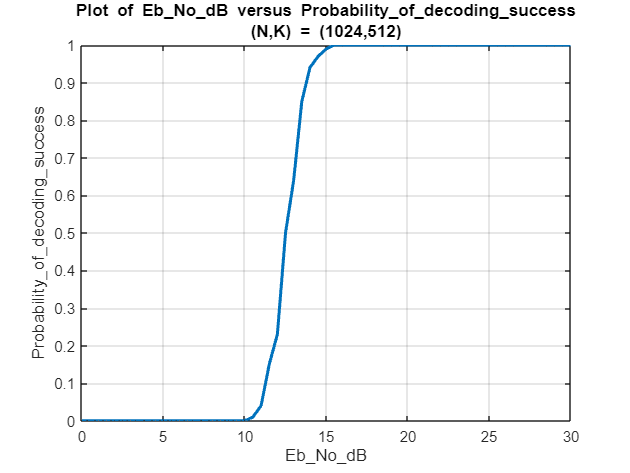

clearvars;
close all;
clc;

tic
load('Reliability_Sequence.mat');
N = 1024;
n = log2(N);
K = 512;

Sequence = Reliability_Sequence(Reliability_Sequence <= N);
Frozen_bits = Sequence(1:N-K);

Nsim = 100;
Eb_No_Range = 0:0.5:30;
Probability_of_decoding_success = zeros(1, length(Eb_No_Range));
Bit_Error_Rate = zeros(1, length(Eb_No_Range));
Block_Errors_Rate = zeros(1, length(Eb_No_Range));
Iteration_index = 1;

for Eb_No = Eb_No_Range
    Successful_Decoding = 0;
    Nsim_block_errors = 0; 
    Nsim_bit_errors = 0;

    for block = 1:Nsim
        message_sequence = randi([0 1], 1, K);
        message = zeros(1, N);
        message(Sequence(N-K+1:end)) = message_sequence;
        
        code_word = Polar_Encoding(message, n);
        code_word = BPSK_AWGN_Introduction(code_word, Eb_No, K, N);
        
        message_cap = Polar_Hard_Decode(code_word, N);
        message_cap = message_cap(Sequence(N-K+1:end));
   
        Evident_errors = sum(message_sequence ~= message_cap);
        if(Evident_errors == 0)
            Successful_Decoding = Successful_Decoding + 1;
        else
            Nsim_bit_errors = Nsim_bit_errors + Evident_errors;
            Nsim_block_errors = Nsim_block_errors + 1;
        end
    end

    Probability_of_decoding_success(Iteration_index) = (1/Nsim)*Successful_Decoding;
    Bit_Error_Rate(Iteration_index) = Nsim_bit_errors/K/Nsim;
    Block_Errors_Rate(Iteration_index) = Nsim_block_errors/Nsim;
    Iteration_index = Iteration_index + 1;
end

plot(Eb_No_Range, Probability_of_decoding_success, 'LineWidth', 2);
title("Plot of Eb\_No\_dB versus Probability\_of\_decoding\_success" + newline + "(N,K) = (" + num2str(N) + "," + num2str(K) + ")");
xlabel('Eb\_No\_dB');
ylabel('Probability\_of\_decoding\_success');
grid on;

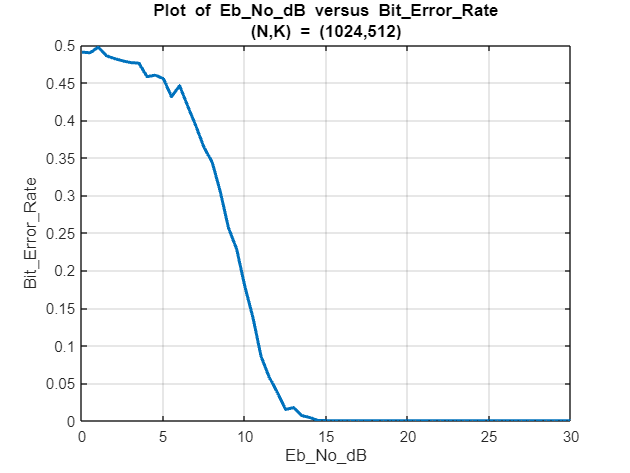

plot(Eb_No_Range, Bit_Error_Rate, 'LineWidth', 2);
title("Plot of Eb\_No\_dB versus Bit\_Error\_Rate" + newline + "(N,K) = (" + num2str(N) + "," + num2str(K) + ")");
xlabel('Eb\_No\_dB');
ylabel('Bit\_Error\_Rate');
grid on;

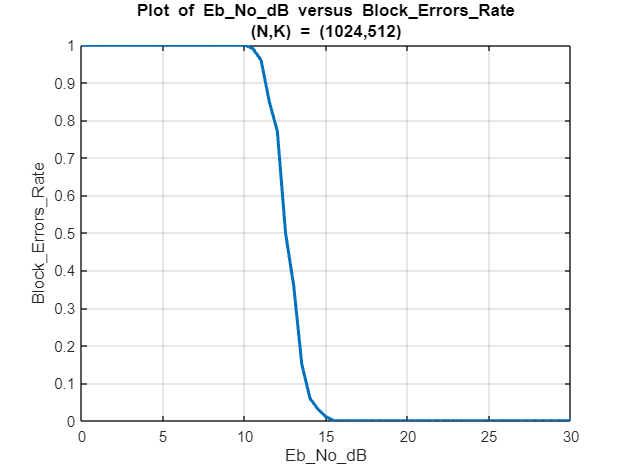

plot(Eb_No_Range, Block_Errors_Rate, 'LineWidth', 2);
title("Plot of Eb\_No\_dB versus Block\_Errors\_Rate" + newline + "(N,K) = (" + num2str(N) + "," + num2str(K) + ")");
xlabel('Eb\_No\_dB');
ylabel('Block\_Errors\_Rate');
grid on;

toc

Elapsed time is 67.473824 seconds.


function code_word = Polar_Encoding(message, bit_length)
    Generator_Matrix = [1 0; 1 1];
    A = Generator_Matrix;
    B = Generator_Matrix;
    for count = 1:bit_length-1
       A = kron(A, B);
    end
    Generator_Matrix = A;
    code_word = mod(message*Generator_Matrix, 2);
end

function code_word = BPSK_AWGN_Introduction(code_word, Eb_No_dB, K, N)
    BPSK_modulated_code_word = 1 - 2*code_word;
    Eb_No = 10^(Eb_No_dB/10);
    Es_No = (K/N) * Eb_No;
    sigma = sqrt(1 / Es_No);
    AWGN = sigma*randn(1, N);
    
    code_word = BPSK_modulated_code_word + AWGN;
end

function Message_cap = Polar_Hard_Decode(received_bits, N)
    Message_cap = zeros(1, N);
    message_index = 1;
    code_word_cap = (received_bits < 0);
    queue = {};
    queue{end+1} = code_word_cap;
    
    while(~isempty(queue))
        element_1 = queue{1};
        queue(1) = [];

        if(length(element_1) == 1)
            Message_cap(message_index) = element_1;
            message_index = message_index + 1;
            continue;
        end

        size = length(element_1);
        a = element_1(1:size/2);
        b = element_1(size/2+1:end);

        left = xor(a, b);
        right = b;
        queue{end+1} = left;
        queue{end+1} = right;
    end
end
